# Kirchhoff laws

The Kirchhoff laws are the fundamental postulates of the lumped-circuit theory. They hold independently of the nature of the circuit elements.

The application of Kirchhoff laws always lead to homogenous linear algebraic equations with the real coefficients.

Note: For the analysis of circuits we arbitrarily assign:

- a reference direction for the current of a branch with an arrow, and

- a reference polarity for the voltage polarity of a pair of nodes with plus/minus (+, −) signs.

## Kirchhoff’s voltage law (KVL)

The algebraic sum of all the voltages around any closed path (or mesh) in a circuit equals 0.

For a path of N branches:


$$\sum_{k=1}^N u_k \left(t\right)\;=0\;\;\;\;\;\;\forall t$$
   

E.g.:

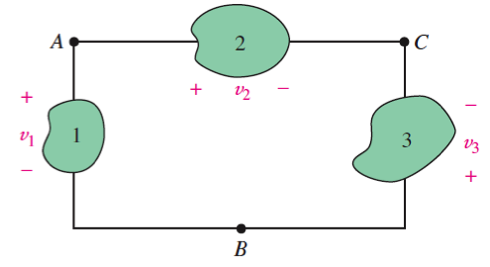


$$v_1 +v_2 +v_3 =0$$


(Possibile) sign convention:

- Positive sign to a voltage rise across a branch.

- Negative sign to a voltage drop across a branch.

## Kirchhoff’s current law (KCL)

The algebraic sum of all the currents at any node in a circuit equals 0.

For a node with N elements:


$$\sum_{k=1}^N i_k \left(t\right)\;=0\;\;\;\;\;\;\forall t$$


Or in other words, the sum of the currents entering a node has to be equal to the sum of the output currents:


$$\Sigma \;I_{\textrm{input}} =\;\Sigma \;I_{\textrm{output}}$$


E.g.:

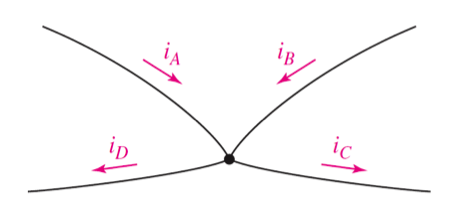


$$i_A +i_B =i_C +i_D$$


(Possibile) sign convention:

- Input currents in a node are negative.

- Output currents in a node are positive.

## General circuit analysis

The analysis of electrical circuits basically consists in writing together Kirchhoff's laws and the constitutive relationship of all the elements in the circuit.

#### General procedure

- Identify all the (essential) nodes of the circuit.

- Identify all the meshes (or the minimum number of loops containing all the elements) of the circuit.

- Assign a direction for the currents in all (essential) branches of the circuit.

- Assign a polarity for the voltages across all the elements of the circuit.

- Write the KCL for all the nodes (except one).

- Write the KVL for all the identified meshes (or loops).

- Write the constitutive relationship for all the elements.

- Solve the system equation.

# Matlab commands to solve a system of equations

- Declare the system of equations with the `syms` command. 

- Write equations.

- Solve the system of equations using `solve`. The inputs to `solve` are a vector of equations, and a vector of variables to solve the equations for.

**E.g.:**

syms x1 x2 x3
EQ1 = x1 + x2 + x3 == 9;
EQ2 = x1 - x2 -x3 == 3;
EQ3 = x1 + 2*x2+ 3*x3 == 13;
sol = solve([EQ1,EQ2,EQ3], [x1,x2,x3]);
x1Sol = sol.x1

$$x1Sol = 6$$

x2Sol = sol.x2

$$x2Sol = 2$$

x3Sol = sol.x3

$$x3Sol = 1$$

## Exercise

Find the value of i1 if:

R1 = 4Ω, R2 = 2Ω, R4 = R5 = 8Ω, Us = 10V, Is = 2A.

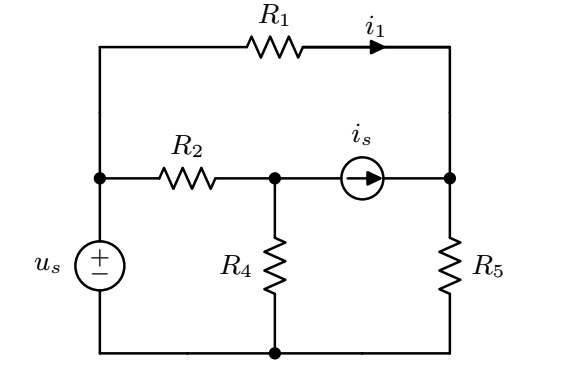

R1=4; R2=5; R4=8; R5=8;

R1 = 4

Us=10; Is=2;

Declare the system of equations:

syms i1,...

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

KVL:

KVL1...;

KCL:

KCL1...;

Solve the system of equations using `solve`. The inputs to `solve` are a vector of equations, and a vector of variables to solve the equations for.

sol = solve([KVL1...], [i1]);
i1Sol = sol.i1
...

**Solution:**

i1 = -0.5A

**Resolution:**

We identify the nodes and meshes (in blue) of the circuit, and we assign names and directions for the currents and voltages (in orange and purple).

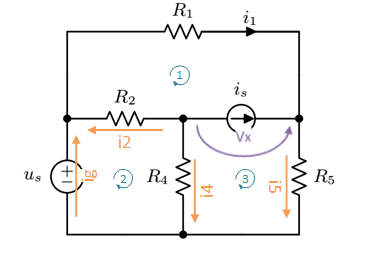

Declare the system of equations.

syms i1 i2 i4 i5 ig Vx

KVL for the 3 meshes:

KVL1 = R1*i1 + Vx + R2*i2 == 0;
KVL2 = -R2*i2 + R4*i4 - Us == 0;
KVL3 = R5*i5 - R4*i4 - Vx == 0;

KCL for the 3 (4-1) nodes:

KCL1= ig + i2 == i1;
KCL2= i1 + Is == i5;
KCL3= i4 + i5 == ig;
% The 4th KCL is: KCL4 = i2 + i4 + Is == 0
% We could replace any of the KCLs for this one and still obtain the same
% result.

Solve the system of equations using `solve`. The inputs to `solve` are a vector of equations, and a vector of variables to solve the equations for.

sol = solve([KVL1, KVL2, KVL3, KCL1, KCL2, KCL3], [i1, i2, i4,i5,ig,Vx]);

$$i1Sol = -\frac{1}{2}$$

$$i2Sol = -2$$

$$i4Sol = 0$$

$$i5Sol = \frac{3}{2}$$

$$igSol = \frac{3}{2}$$

$$VxSol = 12$$

i1Sol = sol.i1
i2Sol = sol.i2
i4Sol = sol.i4
i5Sol = sol.i5
igSol = sol.ig
VxSol = sol.Vx